# No sharing of resources

Num_individuals=100;
Num_time_steps=120;
nut_init=50;
m_for=1;
m_nur=1;
mu=50;
nutrition_levels = nut_init*(0.9 + 0.2*rand(Num_individuals,1));

nutrition_levels =    54.3734
   53.8314
   52.0660
   49.1820
   54.4630
   45.8506
   52.1249
   45.5372
   48.3426
   47.5987



%In our simulation, nursing will be denoted by 1, and foraging by 2
worker_roles = ones(Num_individuals,Num_time_steps); %Initially workers all nurse until they are stimulated to go forage
food = 0; %Initialising no food available
R=4; %Amount of food collected by each forager
num_foragers=zeros(1,Num_time_steps); %Initialising number of foragers

for time = 1:Num_time_steps
    for worker = 1:Num_individuals
        perception_err = -1+ 2*rand(); %Error with which they perceive their own hunger
        if nutrition_levels(worker) + perception_err<= mu
            worker_roles(worker,time) = 2;
        else
            worker_roles(worker,time)=1;
        end

        if worker_roles(worker,time)==1
            nutrition_levels(worker) =nutrition_levels(worker)-m_nur;
        else %if the role was 2
            nutrition_levels(worker) = nutrition_levels(worker)-m_for+R;
        end

    end
        num_foragers(1,time) = sum(worker_roles(:,time)==2);
end

## Number of nursers and foragers over time plot

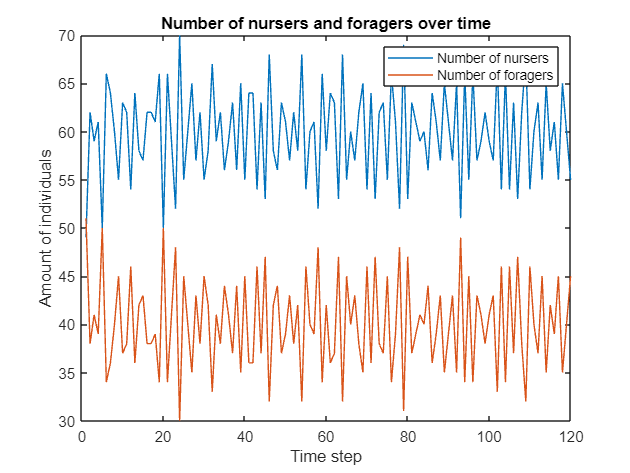

plot(100-num_foragers)
hold on
plot(num_foragers)
hold off
title('Number of nursers and foragers over time')
ylabel('Amount of individuals')
xlabel('Time step')
legend('Number of nursers', 'Number of foragers')

## Nutrition levels of the nursers and foragers plot

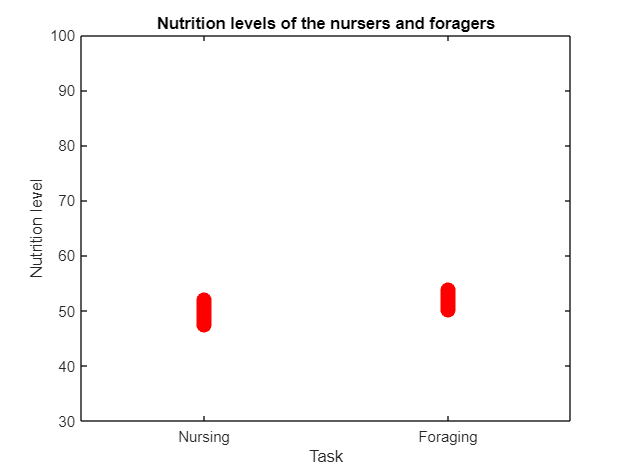

x = worker_roles(:,120);
x_categorical = categorical(x, [1 2], {'Nursing', 'Foraging'});
plot(x_categorical, nutrition_levels, 'r.', 'MarkerSize', 30)

xlabel('Task')
ylim([30, 100])
ylabel('Nutrition level')
title('Nutrition levels of the nursers and foragers')

## Calculation of division of labour

repetitions = zeros(120,1);

for j = 2:120
    for i=1:100
           if worker_roles(i,j)==worker_roles(i,j-1)
                 repetitions(j)=repetitions(j)+1;
           end
    end
end

q = repetitions/Num_individuals

q =          0
    0.5900
    0.2100
    0.2200
    0.1300
    0.1600
    0.3200
    0.2400
    0.1900
    0.2200


p1 = num_foragers./Num_individuals

p1 =     0.5100    0.3800    0.4100    0.3900    0.5000    0.3400    0.3600    0.4000    0.4500    0.3700    0.3800    0.4600    0.3600    0.4200    0.4300    0.3800    0.3800    0.3900    0.3400    0.5000    0.3400    0.4100    0.4800    0.3000    0.4500    0.4000    0.3500    0.4300    0.3800    0.4500    0.4200    0.3300    0.4100    0.3800    0.4400    0.4100    0.3700    0.4400    0.3500    0.4500    0.3600    0.3600    0.4600    0.3700    0.4700    0.3200    0.4200    0.4400    0.3700    0.3900


p2 = (100-num_foragers)./Num_individuals

p2 =     0.4900    0.6200    0.5900    0.6100    0.5000    0.6600    0.6400    0.6000    0.5500    0.6300    0.6200    0.5400    0.6400    0.5800    0.5700    0.6200    0.6200    0.6100    0.6600    0.5000    0.6600    0.5900    0.5200    0.7000    0.5500    0.6000    0.6500    0.5700    0.6200    0.5500    0.5800    0.6700    0.5900    0.6200    0.5600    0.5900    0.6300    0.5600    0.6500    0.5500    0.6400    0.6400    0.5400    0.6300    0.5300    0.6800    0.5800    0.5600    0.6300    0.6100



D = [];
for i =1:length(q)
    D(i) = q(i)./(p1(i).^2 + p2(i).^2) - 1;
end

## Division of labour over time plot

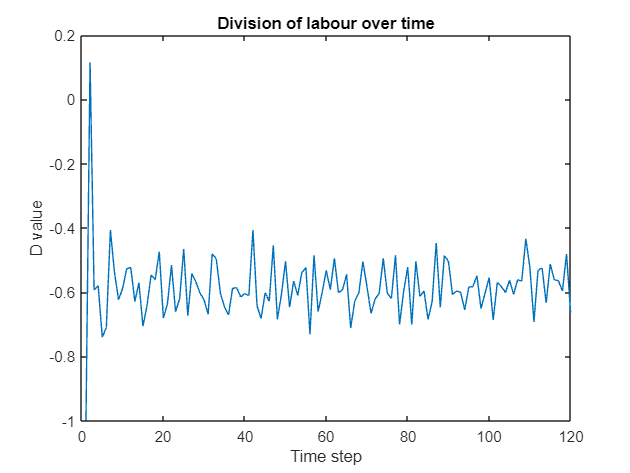

plot(1:Num_time_steps, D)
title('Division of labour over time')
ylabel('D value')
xlabel('Time step')